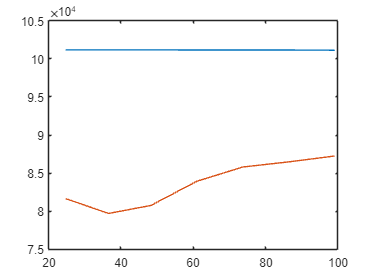

clear

staticP = zeros(1,11);
totalP = zeros(1, 7);

for i = (1:7)
    data = load("Data/231012_Group05_Subsonic_Total_"+i+".mat");
    
    t = (1:2500);
    
    %data.dataP_mean
    
    %swapping 4 & 5: 
    v = data.dataP_mean(:,4);
    data.dataP_mean(:, 4) = data.dataP_mean(:, 5);
    data.dataP_mean(:, 5) = v;
    
    %swapping 10 & 11: 
    v = data.dataP_mean(:,10);
    data.dataP_mean(:, 10) = data.dataP_mean(:, 11);
    data.dataP_mean(:, 11) = v;
    
    %data.dataP_mean
    %plot(t, dataP_mean);

    staticP = staticP + data.dataP_mean(1:11);
    totalP(i) = data.dataP_mean(12);
    
    %avgP = data.dataP_mean;
    %x = (1:10);
    %plot(x, avgP(1:10))
    %hold on;

    clear data

end

staticP = staticP/7;
totalP;

x = [24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118, 209.5, 300.1];
plot(x(1:7),totalP) 
hold on;
plot(x(1:7),staticP(1:7))
hold off;

g = 1.4

g = 1.4000

R = 8.314/0.02897

R = 286.9865

rho = 1.266 %kg/m^3 at 20 degree C 

rho = 1.2660

M_exp = zeros(1,7);

for i = (1:7)
    M_exp(i) = abs(sqrt( (2/(g-1)) * ( (totalP(i)/staticP(i))^((g-1)/g) -1 )) );
end

%plot(x(1:7), M_exp)

% theoretical calculations: 
% assuming incompressible flow since the experimental dynamic pressure is
% constant everwhere

% using the pressure from pos 2 as reference, vel at that pos:

U_ref = sqrt(2*(totalP(2)-staticP(2)) / rho);

% using coninuity equation:

Ar = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28]; % area ratios relative to nozzle
vel = @(n) Ar(n).^(-1) * U_ref;

U = zeros(1,7);
U = vel(1:7);

a = sqrt(g*R*298); %/1.12

M_theo = U/a;

%finding the P dist: 

pres = @(n) totalP(2) - 0.5*rho*U(n).^2;

p_theo = zeros(1,7);
p_theo = pres(1:7);




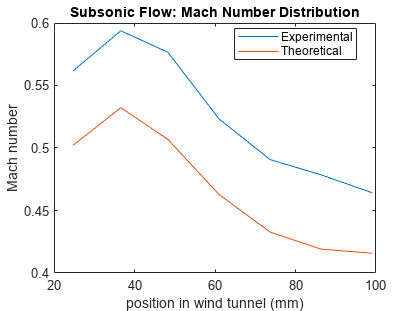

P = zeros(2, 7);
P_error = zeros(2, 7);
y = 1.4;

P(1, :) = staticP(1:7);
P(2, :) = totalP;


%hold on;
plot(x(1:7), M_exp, 'DisplayName', 'Experimental')
hold on;
plot(x(1:7), M_theo, 'DisplayName', 'Theoretical')
title("Subsonic Flow: Mach Number Distribution")
legend(Location="best")
xlabel("position in wind tunnel (mm)");
ylabel("Mach number");
saveas(gcf,"Figures\SubMachNumbDist.png")
hold off;

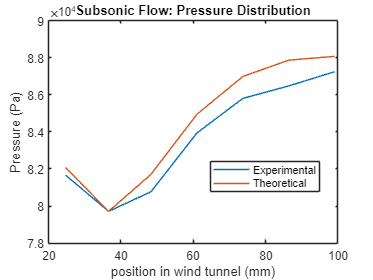


plot(x(1:7), staticP(1:7), 'DisplayName', 'Experimental');
hold on;
plot(x(1:7), p_theo, 'DisplayName', 'Theoretical')
title("Subsonic Flow: Pressure Distribution")
legend(Location="best")
xlabel("position in wind tunnel (mm)");
ylabel("Pressure (Pa)");
saveas(gcf,"Figures\SubPresNumbDist.png")
hold off;